load cond.dat
X = cond;

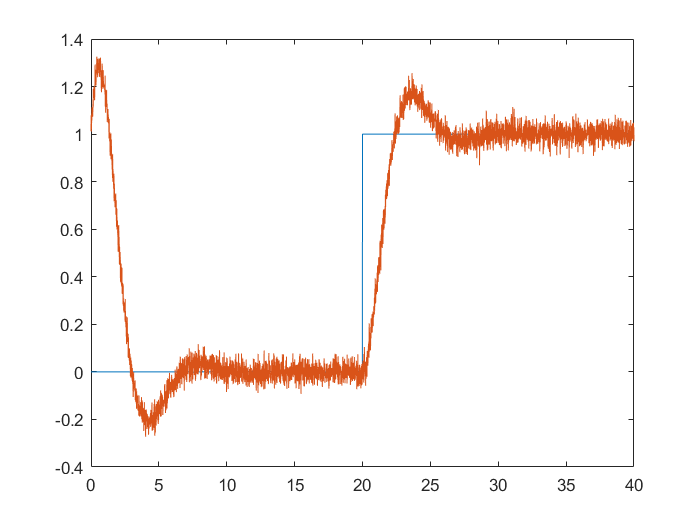

plot(X(:,1),X(:,2)) % Gives a plot of the input vs. sample number 
hold on
plot(X(:,1),X(:,3)) % Gives a plot of the output vs. sample number 
hold off

% Trim data and subtract min
Start = 1501;
Final = 3000;

Y = X(Start:Final,:);

minVal = min(Y(:,3));

for i = Start:Final
    Y(i - Start + 1,3)=X(i,3) - minVal;
end

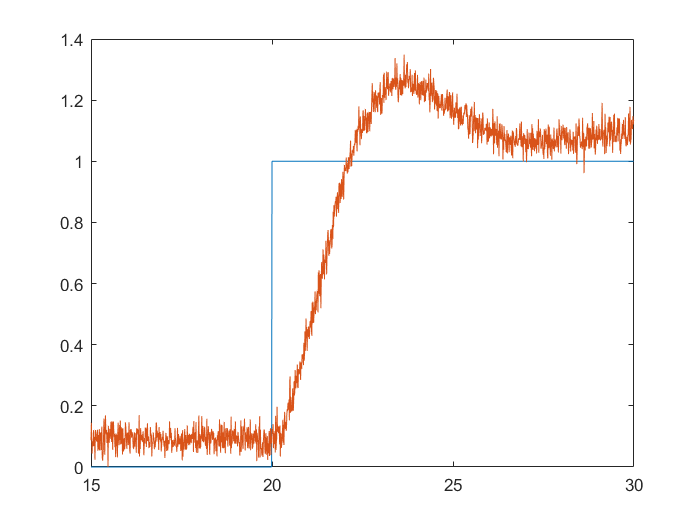

% Plot cropped data

plot(Y(:,1),Y(:,2)) % Gives a plot of the input vs. sample number 
hold on
plot(Y(:,1),Y(:,3)) % Gives a plot of the output vs. sample number 
hold off

% Remove HF noise using low-pass filter
% By observation, the period of the response is around 700 samples long.
% Choose w > 2 pi/700.
w = 0.02;
N = 5;

W = idfilt(Y(:,3), N, w, 'noncausal');

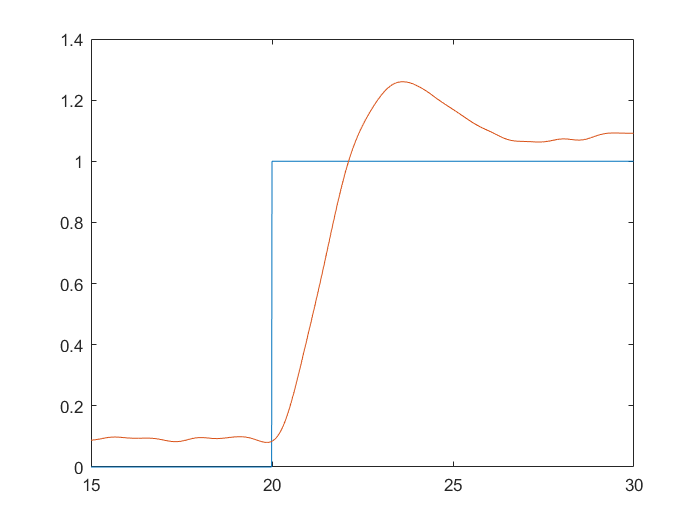

plot(Y(:,1),Y(:,2))
hold on;
plot(Y(:,1), W) % Gives a plot of the input vs. sample number 